# Test Unstable Manifold

## parameters

clear
mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu =         0.0121501137626329



e = 0.4

e =                        0.4


Cr= 1 + e

Cr =                        1.4


Area= 110.5

Area =                      110.5


mass= 8000.0

mass =         8000



Ap = 0.001%rand(1)

Ap =                      0.001


theta = 2*pi*0.001% rand(1)

theta =        0.00628318530717959


## L1 unstable manifold


periodo = 3.205884;
X0 = [0.803317447531650 0 0 0.333418984453424]

X0 =           0.80331744753165                         0                         0         0.333418984453424



C1 = jacobiConstant(X0(1,1:2),X0(1,3:4),mu)

C1 =           3.09461890665891


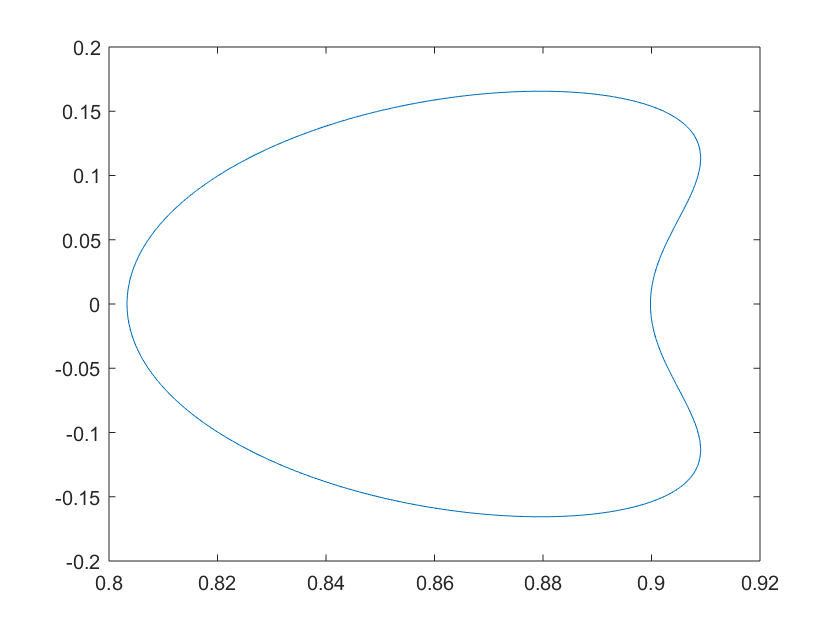

STM = reshape(eye(4),16,[])';
X = [X0 STM]';

%%% plot periodic orbit
numSteps=300;
tspan=linspace(0,periodo,numSteps);
ode__opt = odeset('RelTol',1e-13,'AbsTol',1e-22);
[t, X_periodica] = ode113(@CRTBPLyapunov, tspan,X , ode__opt, mu); 
plot(X_periodica(:,1),X_periodica(:,2))

figure

k = 100

k =    100


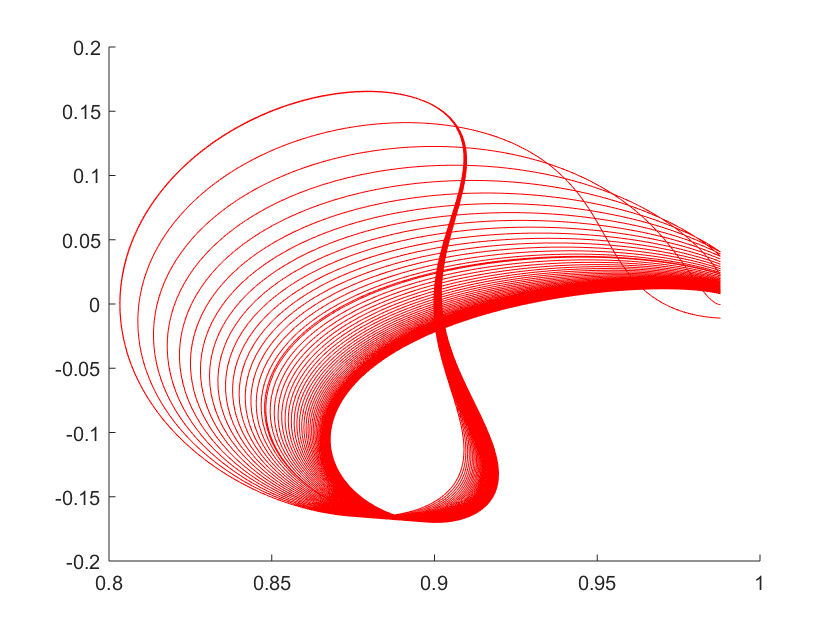

h =      1


epsilon=1e-10;
X_mainfold = calculateUnStableMainfoldPerturbation(periodo,X,mu,k,epsilon,1,true,Ap,theta,Cr,Area,mass);